# Estimate Probability of Default (PD) using a Logistic Model

## Import Data

load CreditData
Data.Rating = categorical(Data.Rating,{'CCC','B','BB','BBB','A','AA','AAA'},'Ordinal',true);
FinancialRatios    = Data(:,2:7);

## Create Random Sample for Training

[Dtrain,idx]     = datasample(Data,round(0.7*height(Data)));
Dtest            = Data;
Dtest(idx,:)     = [];

FinRatio_TrainingSet = Dtrain{:,1:end-1};
Ratings_TrainingSet  = Dtrain.Rating;
FinRatio_TestSet     = Dtest{:,1:end-1};
Ratings_TestSet      = Dtest.Rating;

## Logistic Fit of the data

[B_Training,dev_Training,stats_Training]           = mnrfit(FinRatio_TrainingSet,double(Ratings_TrainingSet),'link','logit','model','ordinal');
[pihat_Training,dlow_Training,dhi_Training]        = mnrval(B_Training,FinRatio_TrainingSet,stats_Training,'link','logit','model','ordinal');
[Prob_RatingEstimated_Training,RatingIdx_Training] = max(pihat_Training,[],2);

[pihat_Testing,dlow_Testing,dhi_Testing]           = mnrval(B_Training,FinRatio_TestSet,stats_Training,'link','logit','model','ordinal');
[Prob_RatingEstimated_Testing,RatingIdx_Testing]   = max(pihat_Testing,[],2);
pihat_Training2View = array2table(round(pihat_Training(1:5,:)),'VariableNames',cellstr(unique(Data.Rating)))

pihat_Training2View = 5×7 table
    CCC      B       BB     BBB      A       AA     AAA 
    ____    ____    ____    ____    ____    ____    ____

    0.00    0.00    0.00    1.00    0.00    0.00    0.00
    0.00    0.00    0.00    1.00    0.00    0.00    0.00
    0.00    0.00    1.00    0.00    0.00    0.00    0.00
    0.00    0.00    1.00    0.00    0.00    0.00    0.00
    0.00    0.00    0.00    0.00    1.00    0.00    0.00


## Visualization of Matrix_ActualVsEstimated

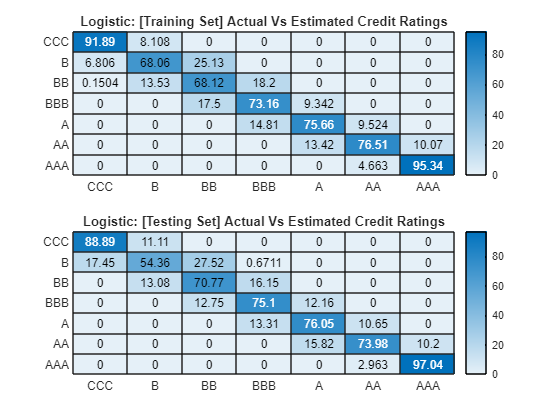

Matrix_ActualVsEstimated_Training = confusionmat(RatingIdx_Training,double(Ratings_TrainingSet));
Matrix_ActualVsEstimated_Training = 100*Matrix_ActualVsEstimated_Training./repmat(sum(Matrix_ActualVsEstimated_Training,2),1,size(Matrix_ActualVsEstimated_Training,2));
Matrix_ActualVsEstimated_Testing  = confusionmat(RatingIdx_Testing,double(Ratings_TestSet));
Matrix_ActualVsEstimated_Testing  = 100*Matrix_ActualVsEstimated_Testing./repmat(sum(Matrix_ActualVsEstimated_Testing,2),1,size(Matrix_ActualVsEstimated_Testing,2));

RatingCategories         = cellstr(unique(Data.Rating));
figure; 
subplot(2,1,1);
heatmap(RatingCategories,RatingCategories,Matrix_ActualVsEstimated_Training)
title('Logistic: [Training Set] Actual Vs Estimated Credit Ratings')
subplot(2,1,2)
heatmap(RatingCategories,RatingCategories,Matrix_ActualVsEstimated_Testing)
title('Logistic: [Testing Set] Actual Vs Estimated Credit Ratings')